Loading images

img1 = imread('ur_c_s_03a_01_L_0376.png');
img2 = imread('ur_c_s_03a_01_L_0377.png');
img3 = imread('ur_c_s_03a_01_L_0378.png');
img4 = imread('ur_c_s_03a_01_L_0379.png');
img5 = imread('ur_c_s_03a_01_L_0380.png');
img6 = imread('ur_c_s_03a_01_L_0381.png');

Displaying in grayscale

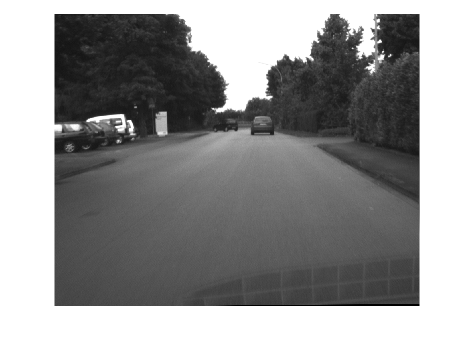

gsimg1 = rgb2gray(img1);
figure, imshow(gsimg1), colormap gray

displaying rgb

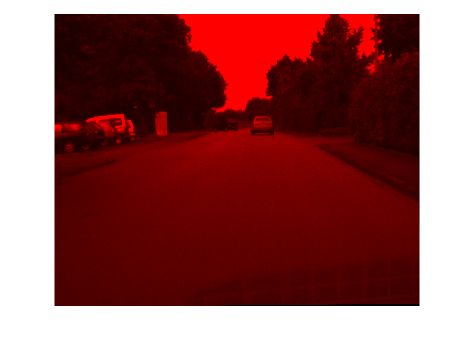

rmap = interp1([0,1],[0 0 0; 1 0 0], linspace(0,1,256));
gmap = interp1([0,1],[0 0 0; 0 1 0], linspace(0,1,256));
bmap = interp1([0,1],[0 0 0; 0 0 1], linspace(0,1,256));


figure, imshow(img1(:,:,1)), colormap(rmap);

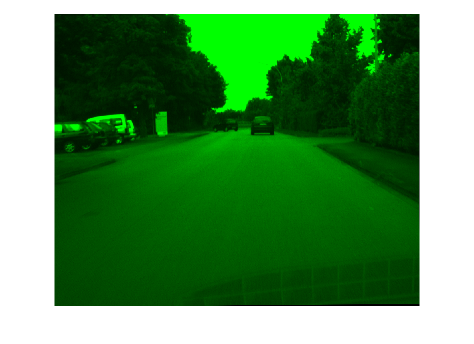

figure, imshow(img1(:,:,2)), colormap(gmap);

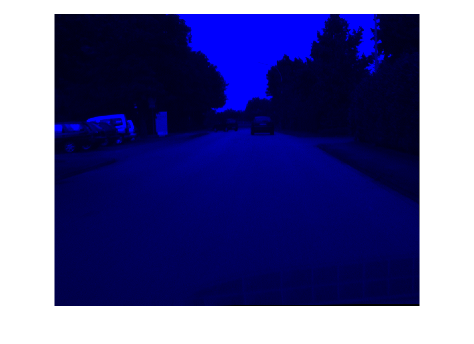

figure, imshow(img1(:,:,3)), colormap(bmap);

displaying hsv

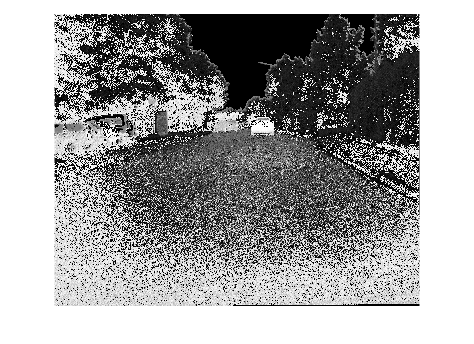

hsvimg = rgb2hsv(img1);

figure, imshow(hsvimg(:,:,1)), colormap gray;

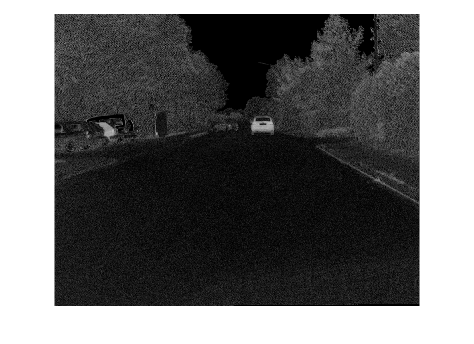

figure, imshow(hsvimg(:,:,2)), colormap gray;

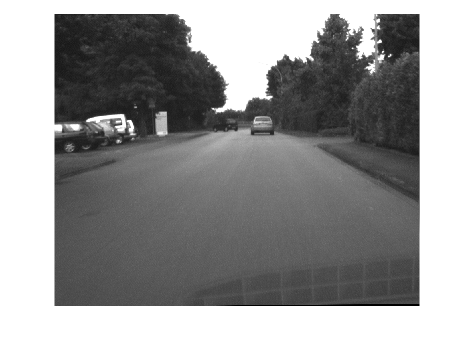

figure, imshow(hsvimg(:,:,3)), colormap gray;

Standard deviation and mean

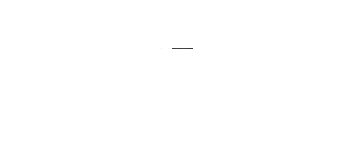

hsvarea = rgb2hsv(img1);
areaH = hsvarea(:,:,1);
AHarea = areaH(390:400,575:595);
figure, imshow(area), colormap gray;

m = mean2(AHarea);
s = std2(AHarea);
"The mean is: "+ m

ans = "The mean is: 0.77408"

"The standard deviation is: " + s

ans = "The standard deviation is: 0.052077"

Black car

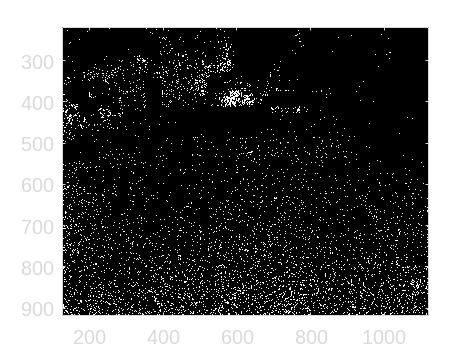

%setting variables
threshold = s;
%uncomment for red car
%m = 0.985;
%s = 0.015;

img = img1;
HSVimg = rgb2hsv(img);
Himg = HSVimg(:,:,1);
THimg = (Himg > (m - threshold)) & (Himg < (m + threshold));
base = zeros(1024, 1280);
res = base + THimg;
figure, imagesc(res), colormap gray

Centroid

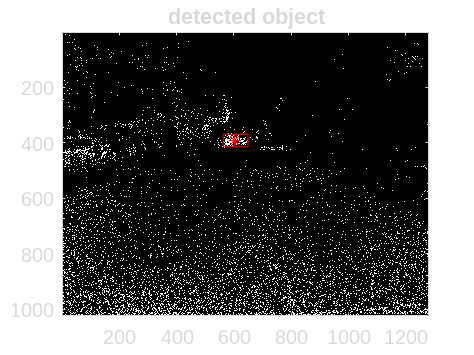

prop=regionprops(THimg,'Area','Centroid','BoundingBox');
[m, i] = max([prop.Area]);
xc=floor(prop(i).Centroid(1));
yc=floor(prop(i).Centroid(2));
ul_corner_width=prop(i).BoundingBox;
figure,imagesc(res),colormap gray,title('detected object')
hold on
plot(xc,yc,'*r')
rectangle('Position',ul_corner_width,'EdgeColor',[1,0,0])

Sunflower

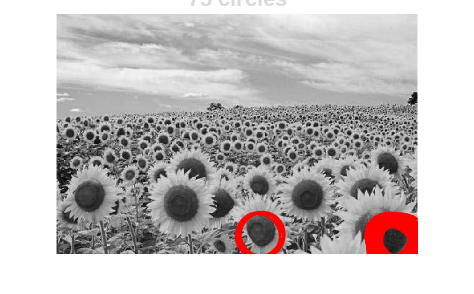

blobs_detection('sunflowers.png',35, 1);